# HW1_1_4

## Filter

close all;
clear;
clc;

In previous homework use convolution function for filtering signal with movingMax filter, but in this project we use filter Function to implement the filter.

Show the diffrences at end.

t   = (0: 0.01: 2);
Amp = 5;
Fs  = 1;

M1  = 0;
M2  = 20;

Func        = Amp*sin(t * Fs *2*pi);
movingAvg   = 1/(M2-M1+1) * ones(1, (M2-M1+1));

NoisyFunc   = Func + rand(1, length(Func));

FilterOut   = filter(movingAvg, 1, NoisyFunc);

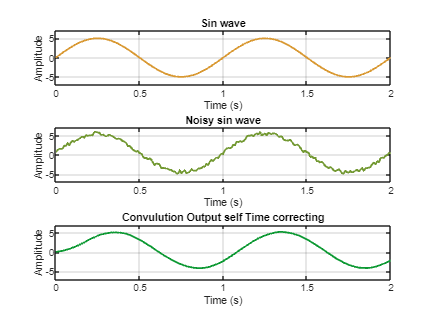

figure('Name', 'Moving Max Filtering')
subplot(3, 1, 1)
plot(t, Func, 'LineWidth', 1.5, 'Color', [0.85, 0.6, 0.2]);
ylim([-7 7])
xlabel('Time (s)');
ylabel('Amplitude');
title('Sin wave');
grid on;
subplot(3, 1, 2)
plot(t, NoisyFunc, 'LineWidth', 1.5, 'Color', [0.45, 0.6, 0.2]);
ylim([-7 7])
xlabel('Time (s)');
ylabel('Amplitude');
title('Noisy sin wave');
grid on;
subplot(3, 1, 3)
plot(t, FilterOut, 'LineWidth', 1.5, 'Color', [0.05, 0.6, 0.2]);
xlim([0 t(end)])
ylim([-7 7])
xlabel('Time (s)');
ylabel('Amplitude');
title('Convulution Output self Time correcting');
grid on;

To implement this Filter we have to know the signal in 10 sample before starting filtering, so we pad zero to signal for make it work correctly.

M1  = -10;
M2  = 10;

Func        = Amp*sin(t * Fs *2*pi);
movingAvg   = 1/(M2-M1+1) * ones(1, (M2-M1+1));

NoisyFunc   = Func + rand(1, length(Func));

t           = (M1*0.01: 0.01: 2);
Func        = [zeros(1, abs(M1)), Func];
NoisyFunc   = [zeros(1, abs(M1)), NoisyFunc];

FilterOut   = filter(movingAvg, 1, NoisyFunc);

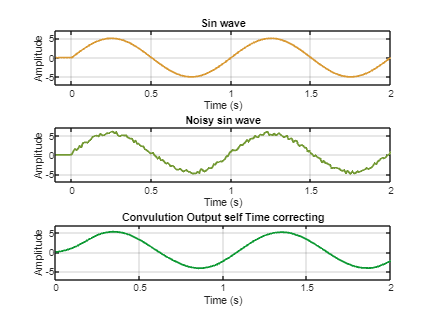

figure('Name', 'Moving Max Filtering')
subplot(3, 1, 1)
plot(t, Func, 'LineWidth', 1.5, 'Color', [0.85, 0.6, 0.2]);
xlim([t(1) t(end)])
ylim([-7 7])
xlabel('Time (s)');
ylabel('Amplitude');
title('Sin wave');
grid on;
subplot(3, 1, 2)
plot(t, NoisyFunc, 'LineWidth', 1.5, 'Color', [0.45, 0.6, 0.2]);
xlim([t(1) t(end)])
ylim([-7 7])
xlabel('Time (s)');
ylabel('Amplitude');
title('Noisy sin wave');
grid on;
subplot(3, 1, 3)
plot(t, FilterOut, 'LineWidth', 1.5, 'Color', [0.05, 0.6, 0.2]);
xlim([0 t(end)])
ylim([-7 7])
xlabel('Time (s)');
ylabel('Amplitude');
title('Convulution Output self Time correcting');
grid on;